% 使用 bayesopt 优化交叉验证分类器
% 此示例说明如何使用 bayesopt 函数优化 SVM 分类。
% 或者，您可以使用 OptimizeHyperparameters 名称-值参数来优化分类器。
% 有关示例，请参阅使用贝叶斯优化优化分类器拟合。
% Optimize Cross-Validated Classifier Using bayesopt
% This example shows how to optimize an SVM classification using the bayesopt function.
% Alternatively, you can optimize a classifier by using 
% the OptimizeHyperparameters name-value argument. 
% For an example, see Optimize Classifier Fit Using Bayesian Optimization.

## 生成数据

分类适用于来自高斯混合模型的点的位置。在 The Elements of Statistical Learning, Hastie、Tibshirani 和 Friedman (2009) 中，第 17 页描述了该模型。该模型首先为“绿色”类生成 10 个基点，分布为具有均值 (1,0) 和单位方差的二维独立法线。它还为“红色”类生成 10 个基点，分布为具有均值 (0,1) 和单位方差的二维独立法线。对于每个类（绿色和红色），生成 100 个随机点，如下所示： 随机均匀地选择一个合适颜色的基点m。 生成具有均值为 m 且方差为 I/5 的二维正态分布的独立随机点，其中 I 是 2×2 单位矩阵。在这个例子中，使用方差 I/50 来更清楚地展示优化的优势。 为每个类生成 10 个基点。 Generate Data The classification works on locations of points from a Gaussian mixture model. In The Elements of Statistical Learning, Hastie, Tibshirani, and Friedman (2009), page 17 describes the model. The model begins with generating 10 base points for a "green" class, distributed as 2-D independent normals with mean (1,0) and unit variance. It also generates 10 base points for a "red" class, distributed as 2-D independent normals with mean (0,1) and unit variance. For each class (green and red), generate 100 random points as follows: Choose a base point m of the appropriate color uniformly at random. Generate an independent random point with 2-D normal distribution with mean m and variance I/5, where I is the 2-by-2 identity matrix. In this example, use a variance I/50 to show the advantage of optimization more clearly. Generate the 10 base points for each class.

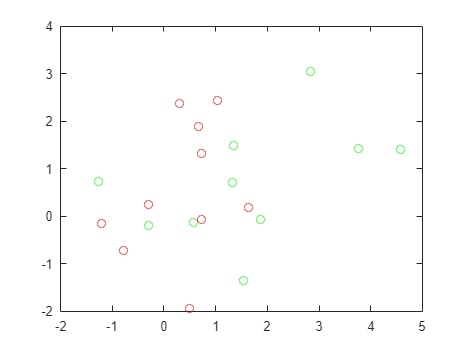

rng('default') % For reproducibility
grnpop = mvnrnd([1,0],eye(2),10);
redpop = mvnrnd([0,1],eye(2),10);
% View the base points.

plot(grnpop(:,1),grnpop(:,2),'go')
hold on
plot(redpop(:,1),redpop(:,2),'ro')
hold off

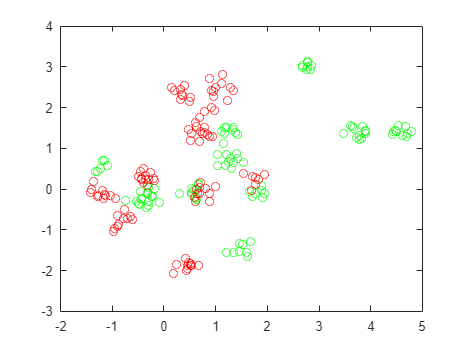


% 由于一些红色基点靠近绿色基点，因此仅根据位置很难对数据点进行分类。
% 生成每个类的 100 个数据点。
% Since some red base points are close to green base points,
% it can be difficult to classify the data points based on location alone.
% Generate the 100 data points of each class.

redpts = zeros(100,2);grnpts = redpts;
for i = 1:100
    grnpts(i,:) = mvnrnd(grnpop(randi(10),:),eye(2)*0.02);
    redpts(i,:) = mvnrnd(redpop(randi(10),:),eye(2)*0.02);
end

% View the data points.
figure
plot(grnpts(:,1),grnpts(:,2),'go')
hold on
plot(redpts(:,1),redpts(:,2),'ro')
hold off

## 准备分类数据

将数据放入一个矩阵中，并制作一个向量 grp 标记每个点的类别。 1表示绿色类，-1表示红色类。 Prepare Data For Classification Put the data into one matrix, and make a vector grp that labels the class of each point. 1 indicates the green class, and -1 indicates the red class.

cdata = [grnpts;redpts];
grp = ones(200,1);
grp(101:200) = -1;

## 准备交叉验证

为交叉验证设置一个分区。 此步骤修复了优化在每个步骤中使用的训练集和测试集。 Prepare Cross-Validation Set up a partition for cross-validation. This step fixes the train and test sets that the optimization uses at each step.

c = cvpartition(200,'KFold',10);

% 为贝叶斯优化准备变量
% 设置一个函数，该函数接受输入 z = [rbf_sigma,boxconstraint] 并返回 z 的交叉验证损失值。 将 z 的分量作为 1e-5 和 1e5 之间的正对数转换变量。 选择范围很广，因为您不知道哪些值可能是好的。
% Prepare Variables for Bayesian Optimization
% Set up a function that takes an input z = [rbf_sigma,boxconstraint] and returns the cross-validation loss value of z. Take the components of z as positive, log-transformed variables between 1e-5 and 1e5. Choose a wide range, because you don't know which values are likely to be good.

sigma = optimizableVariable('sigma',[1e-5,1e5],'Transform','log');
box = optimizableVariable('box',[1e-5,1e5],'Transform','log');

## 目标函数

此函数句柄计算参数 [sigma,box] 处的交叉验证损失。 有关详细信息，请参阅 kfoldLoss。 bayesopt 将变量 z 作为单行表传递给目标函数。 Objective Function This function handle computes the cross-validation loss at parameters [sigma,box]. For details, see kfoldLoss. bayesopt passes the variable z to the objective function as a one-row table.

minfn = @(z)kfoldLoss(fitcsvm(cdata,grp,'CVPartition',c,...
    'KernelFunction','rbf','BoxConstraint',z.box,...
    'KernelScale',z.sigma));

## 优化分类器

使用 bayesopt 搜索最佳参数 [sigma,box]。 为了重现性，请选择“预期改进加”采集功能。 默认采集函数取决于运行时间，因此可以给出不同的结果。 Optimize Classifier Search for the best parameters [sigma,box] using bayesopt. For reproducibility, choose the 'expected-improvement-plus' acquisition function. The default acquisition function depends on run time, and so can give varying results.

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        sigma |          box |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |        0.61 |    0.078152 |        0.61 |        0.61 |   0.00013375 |        13929 |
|    2 | Best   |       0.345 |    0.091827 |       0.345 |       0.345 |        24526 |        1.936 |
|    3 | Accept |        0.61 |    0.099195 |       0.345 |       0.345 |    0.0026459 |   0.00084929 |
|    4 | Accept |       0.345 |    0.051495 |       0.345 |       0.345 |       3506.3 |   6.7427e-05 |
|    5 | Accept |       0.345 |    0.056167 |       0.345 |       0.345 |       9135.2 |       571.87 |
|    6 | Accept |       0.345 |    0.057698 |       0.345 |     

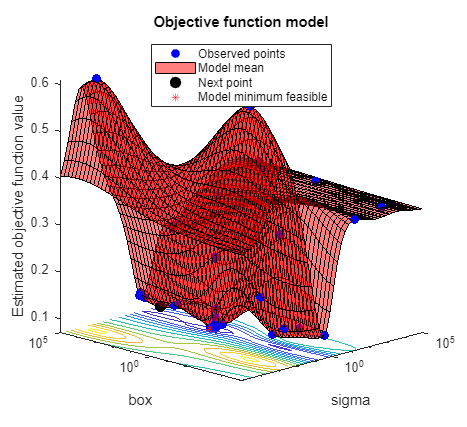

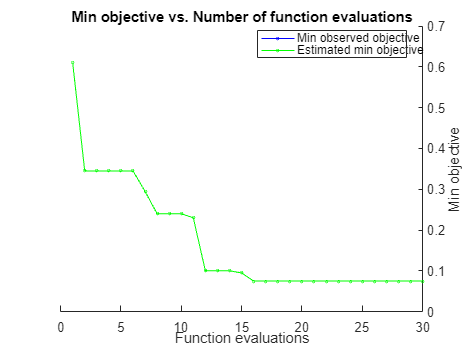

results =   BayesianOptimization with properties:

                      ObjectiveFcn: @(z)kfoldLoss(fitcsvm(cdata,grp,'CVPartition',c,'KernelFunction','rbf','BoxConstraint',z.box,'KernelScale',z.sigma))
              VariableDescriptions: [1×2 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: 0.0750
                   XAtMinObjective: [1×2 table]
             MinEstimatedObjective: 0.0750
          XAtMinEstimatedObjective: [1×2 table]
           NumObjectiveEvaluations: 30
                  TotalElapsedTime: 16.6231
                         NextPoint: [1×2 table]
                            XTrace: [30×2 table]
                    ObjectiveTrace: [30×1 double]
                  ConstraintsTrace: []
                     UserDataTrace: {30×1 cell}
      ObjectiveEvaluationTimeTrace: [30×1 double]
                IterationTimeTrace: [30×1 double]
      

results = bayesopt(minfn,[sigma,box],'IsObjectiveDeterministic',true,...
    'AcquisitionFunctionName','expected-improvement-plus')


% 从 XAtMinEstimatedObjective 属性或使用 bestPoint 函数获取最佳估计可行点。 默认情况下，bestPoint 函数使用“min-visited-upper-confidence-interval”标准。 有关详细信息，请参阅 bestPoint 的 Criterion 名称-值参数。
% Obtain the best estimated feasible point from the XAtMinEstimatedObjective property or by using the bestPoint function. By default, the bestPoint function uses the 'min-visited-upper-confidence-interval' criterion. For details, see the Criterion name-value argument of bestPoint.

results.XAtMinEstimatedObjective

ans = 1×2 table
     sigma      box  
    _______    ______

    0.32869    18.076


% ans=1×2 table
%      sigma      box  
%     _______    ______
% 
%     0.32869    18.076

z = bestPoint(results)

z = 1×2 table
     sigma      box  
    _______    ______

    0.32869    18.076


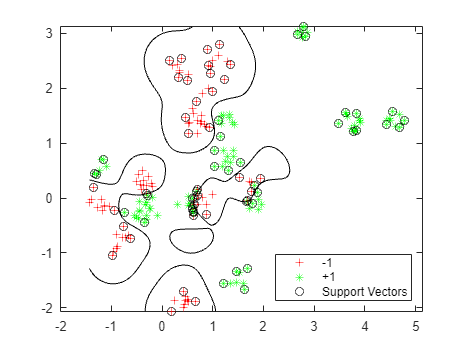

% z=1×2 table
%      sigma      box  
%     _______    ______
% 
%     0.32869    18.076

% 使用最佳点来训练一个新的、优化的 SVM 分类器。
% Use the best point to train a new, optimized SVM classifier.

SVMModel = fitcsvm(cdata,grp,'KernelFunction','rbf', ...
    'KernelScale',z.sigma,'BoxConstraint',z.box);

% 要可视化支持向量分类器，预测网格上的分数。
% To visualize the support vector classifier, predict scores over a grid.

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(cdata(:,1)):d:max(cdata(:,1)), ...
    min(cdata(:,2)):d:max(cdata(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(SVMModel,xGrid);

% 绘制分类边界。
% Plot the classification boundaries.

figure
h(1:2) = gscatter(cdata(:,1),cdata(:,2),grp,'rg','+*');
hold on
h(3) = plot(cdata(SVMModel.IsSupportVector,1) ,...
    cdata(SVMModel.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'},'Location','Southeast');

## 评估新数据的准确性

生成和分类新的测试数据点。 Evaluate Accuracy on New Data Generate and classify new test data points.

grnobj = gmdistribution(grnpop,.2*eye(2));
redobj = gmdistribution(redpop,.2*eye(2));

newData = random(grnobj,10);
newData = [newData;random(redobj,10)];
grpData = ones(20,1);  % green = 1
grpData(11:20) = -1; % red = -1

v = predict(SVMModel,newData);

% 计算测试数据集的误分类率。
% Compute the misclassification rates on the test data set.

L = loss(SVMModel,newData,grpData)

L = 0.3500

% L = 0.3500

## 查看哪些新数据点被正确分类。

用红色圈出正确分类的点，用黑色圈出分类错误的点。 See which new data points are correctly classified. Circle the correctly classified points in red, and the incorrectly classified points in black.

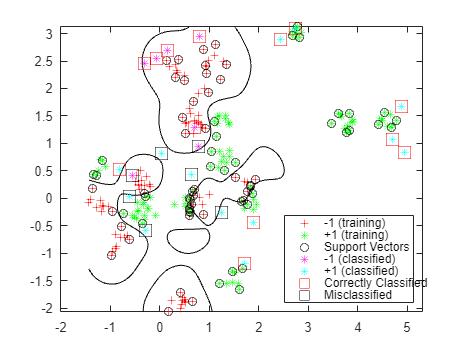

h(4:5) = gscatter(newData(:,1),newData(:,2),v,'mc','**');

mydiff = (v == grpData); % Classified correctly

for ii = mydiff % Plot red squares around correct pts
    h(6) = plot(newData(ii,1),newData(ii,2),'rs','MarkerSize',12);
end

for ii = not(mydiff) % Plot black squares around incorrect pts
    h(7) = plot(newData(ii,1),newData(ii,2),'ks','MarkerSize',12);
end
legend(h,{'-1 (training)','+1 (training)','Support Vectors', ...
    '-1 (classified)','+1 (classified)', ...
    'Correctly Classified','Misclassified'}, ...
    'Location','Southeast');
hold off